## SHALLOW LEARNING

#### Playing with MATLAB's FITRNET Function

Inbuilt function to train a regression neural net

This appears to just be an ANN

rng("default")

N = 15000; %datapoints
m = 10; %num input features
input_data = [rand(N,m)] %input data normalised to btwn 0 and 1

input_data =     0.8147    0.2858    0.8252    0.1839    0.6388    0.3175    0.8937    0.2068    0.0886    0.3919
    0.9058    0.9312    0.0908    0.0488    0.2237    0.6382    0.8162    0.4302    0.4828    0.6212
    0.1270    0.7999    0.2064    0.5280    0.1693    0.2119    0.9474    0.9661    0.9015    0.4001
    0.9134    0.3311    0.7932    0.6577    0.3909    0.4541    0.2403    0.8127    0.5778    0.4569
    0.6324    0.7374    0.6817    0.3300    0.4590    0.5029    0.5797    0.6967    0.9693    0.3711
    0.0975    0.5674    0.4700    0.1683    0.8454    0.7209    0.1888    0.1507    0.4572    0.4465
    0.2785    0.0161    0.8978    0.1655    0.5333    0.5400    0.3513    0.8656    0.8015    0.2468
    0.5469    0.4255    0.4085    0.0459    0.0713    0.1541    0.6063    0.7257    0.3339    0.0212
    0.9575    0.0294    0.6585    0.2291    0.3536    0.1219    0.6446    0.5820    0.1271    0.1138
    0.9649    0.7842    0.9584    0.5768    0.9280    0.5349    0.6153    0.12


powers = randi([1,6],[1,m])

powers =      5     3     5     1     5     1     6     2     5     6


coeffs = [randn(m,1)]

coeffs =     0.6616
   -0.1329
    1.6312
    1.6487
   -0.2863
    0.6266
    0.8173
   -0.9155
    0.0620
    1.6330


const = rand(1)

const = 0.2846

actual_model = @(X) X*coeffs+const + 0.2.*sin(X*coeffs);

[output_data, shift, scale] = normalize(actual_model(input_data))

output_data =     0.4975
   -0.4860
   -1.0178
    0.4903
   -0.1764
   -0.8510
   -0.8117
   -2.0834
   -0.6044
    2.5352


shift = 3.1847

scale = 0.8260


partition_variable = cvpartition(N, "Holdout",0.3);
trainingIndices = training(partition_variable);
trainInput = input_data(trainingIndices,:);
trainOutput = output_data(trainingIndices,:);

testIndices = test(partition_variable);
testInput = input_data(testIndices,:);
testOutput = output_data(testIndices,:);


allModels = {};
i = 1;
lambda = [1e-8,1e-7, 1e-6,1e-5, 2e-5, 1e-4, 2e-4, 5e-4, 1e-3, 2e-3, 5e-3, 0.01, 0.02, 0.04, 0.08, 0.16, 0.32, 0.64, 1.28];

for L = drange(lambda)
    allModels(i) = {fitrnet(trainInput, trainOutput, 'Standardize', false, ...
    'LayerSizes', [5,5], 'Lambda', L)};
    i = i+1;
end

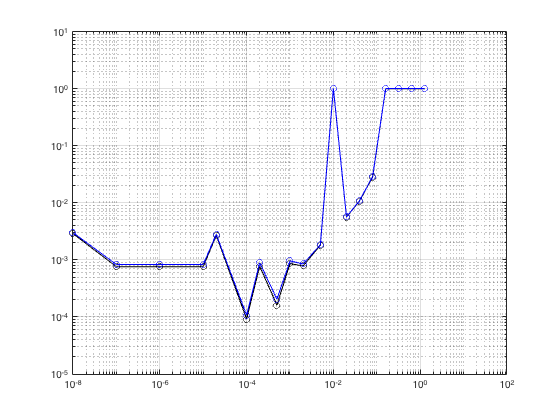


trainLoss = [];
testLoss = [];
for i=1:length(lambda)
    trainLoss(i) = loss(allModels{i}, trainInput, trainOutput);;
    testLoss(i) = loss(allModels{i}, testInput, testOutput);
end
clf
loglog(lambda, trainLoss, '-ok')
hold on
loglog(lambda, testLoss, '-ob')

grid on

InputCheck = rand([1,10])
fprintf('Actual -> %.4f', actual_model(InputCheck))
fprintf('Predicted -> %.4f', predict(allModels{3}, InputCheck)*scale+shift)


#### Playing with Patternnet

Same example as above

The perform function uses MSE but seems to be a lot higher than just calculating the MSE myself??

net = patternnet([5,5]);
% net.numInputs = m;
net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'purelin';
net.layers{3}.transferFcn = 'purelin';
% net.performParam.regularization = 1e-4;
net.performFcn = 'mse';
% net.inputConnect = [ones(1,m); zeros(2,m)];
% net.trainFcn = 'trainbfg';
% view(net)
% trainInputCell = mat2cell(trainInput', [ones(1,m)], [length(trainInput)]);
% trainOutputCell = mat2cell(trainOutput', [ones(1,1)], [length(trainOutput)]);
% 
% testInputCell = mat2cell(testInput', [ones(1,m)], [length(testInput)]);
% testOutputCell = mat2cell(testOutput', [ones(1,1)], [length(testOutput)]);

% net = train(net, trainInput', trainOutput')
% perform(net, testInput', testOutput')


mse_history = [];
training_data_sizes = floor(logspace(0,4,12));
for i=training_data_sizes
    tempnet = net; %must reset net between iterations
%     trainInputCell = mat2cell(trainInput(1:i,:)', [ones(1,m)], [i]);
%     trainOutputCell = mat2cell(trainOutput(1:i,:)', [ones(1,1)], [i]);

    tempnet = train(tempnet, trainInput(1:i,:)', trainOutput(1:i,:)');
%     [i, perform(tempnet, trainInput, trainOutput), perform(tempnet, testInput, testOutput)]
    mse_history = [mse_history; mean((trainOutput' - tempnet(trainInput')).^2), mean((testOutput' - tempnet(testInput')).^2)];
end
net = tempnet;

clf
loglog(training_data_sizes, mse_history(:,1))
hold on
loglog(training_data_sizes, mse_history(:,2))
grid on
xlabel("Size of Dataset")
ylabel("MSE")

InputCheck = rand([10,1]);
fprintf('Actual -> %.4f', actual_model(InputCheck'))
fprintf('Predicted -> %.4f', tempnet(InputCheck)*scale+shift)

play_in = 0:0.05:1;
clf
plot(play_in, actual_model([play_in', zeros(length(play_in),m-1)]))
hold on
plot(play_in, net([play_in', zeros(length(play_in),m-1)]'))
grid on


#### Random Forest

Was used by Q. Xie in "Machine Learning Methods for Real-Time Blood Pressure Measurement Based on Photoplethysmography". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### LSTM 

Was used by L. Harfiya in "Continuous Blood Pressure Estimation Using Exclusively Photopletysmography by LSTM-Based Signal-to-Signal Translation". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### Support Vector Machine Regression

https://towardsdatascience.com/unlocking-the-true-power-of-support-vector-regression-847fd123a4a0

rsvmModel = fitrsvm(trainInput, trainOutput);

frpintf("Converged? %i", rsvmModel.ConvergenceInfo.Converged)

rsvmModel

i = randi(length(testInput));
fprintf("Actual Model -> %.4f", actual_model(testInput(i,:)))
fprintf("Predicted Model -> %.4f", predict(rsvmModel, testInput(i,:)).*scale+shift)



### Playing With Actual Data

%for feature files if the files are too big, tall arrays may be needed
[inputdata, outputdata, normFactors] = MLFeatureRead();

input features has 13725 rows and 612 columns 
output features has 13725 rows and 605 columns 



partition_variable = cvpartition(height(inputdata), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInput = inputdata(trainingIndices,:);
trainOutput = outputdata(trainingIndices,:);

testIndices = test(partition_variable);
testInput = inputdata(testIndices,:);
testOutput = outputdata(testIndices,:);

clf
scatter(inputdata.PPGBW, outputdata.ABPBW)

% xtitle("PPG Bandwidth(norm)")
% ytitle("ABP Bandwidth(norm)")

clf
scatter(inputdata.CT, outputdata.MAP)


clf
scatter(inputdata.RespRate, outputdata.MeanSBP)

rsvmmodel = fitrsvm(trainInput, trainOutput.MAP, 'KernelFunction', 'linear',...
    'KernelScale', 1);

actualMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(rsvmmodel, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;
% testingError = testingError(find(~isnan(testingError)));

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rsvmmodel, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;
% trainingError = trainingError(find(~isnan(trainingError)));

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError(find(~isnan(testingError))))).*100)

Average MAP test error: 9.32%

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError(find(~isnan(trainingError))))).*100)

Average MAP train error: 9.16%

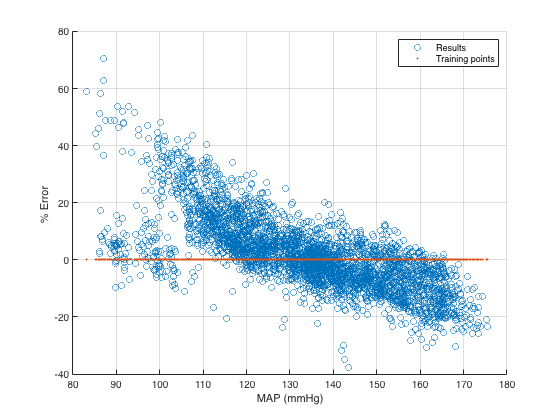


clf
scatter(actualMAP, testingError.*100);
hold on
scatter(actualMAP, 0.*actualMAP, '.')
xlabel("MAP (mmHg)")
ylabel("% Error ")
grid on
legend("Results", "Training points")

rng default
rsvmmodel_opt = fitrsvm(trainInput, trainOutput.MAP, 'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus', 'UseParallel', true));

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       3 | Best   |    0.015215 |      6.6696 |    0.015215 |    0.015215 |       27.209 |     0.011201 |       2.7307 |
|    2 |       3 | Accept |    0.015215 |      6.9131 |    0.015215 |    0.015215 |     0.011062 |       545.55 |       7.2124 |
|    3 |       4 | Accept |    0.015215 |      3.7663 |    0.015215 |    0.015215 |       16.258 |     0.011103 |        11.56 |
|    4 |    


actualMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(rsvmmodel_opt, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rsvmmodel_opt, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;


clf
scatter(actualMAP, testingError.*100);
xlabel("MAP (mmHg)")
ylabel("% Error ")
grid on

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)
fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

#### ANN

[5,5]

rnetModels2_5={};
dataSizes = floor(logspace(0, log10(height(trainInput)),20 ));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels2_5{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [5,5], 'Lambda', 0);

    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels2_5{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels2_5{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
ylim([0,45])
title("[5,5]")
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100 )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

% fprintf("-- rANN --")
% fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)
% fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)


rnetModels2_5a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
    'LayerSizes', [5,5], 'Lambda', 0);

actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels2_5a, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% notNanIdx = find(~isnan(predictedTestMAP));
% predictedTestMAP  = predictedTestMAP(notNanIdx);
% actualTestMAP = actualTestMAP(notNanIdx);
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP)

testingError = 0.0778


actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels2_5a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% notNanIdx = find(~isnan(predictedTrainMAP));
% predictedTrainMAP  = predictedTrainMAP(notNanIdx);
% actualTrainMAP = actualTrainMAP(notNanIdx);
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP)

trainingError = 0.0638


fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

Average MAP train error: 6.38%

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)

Average MAP test error: 7.78%



clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

[50,50, 50, 50]

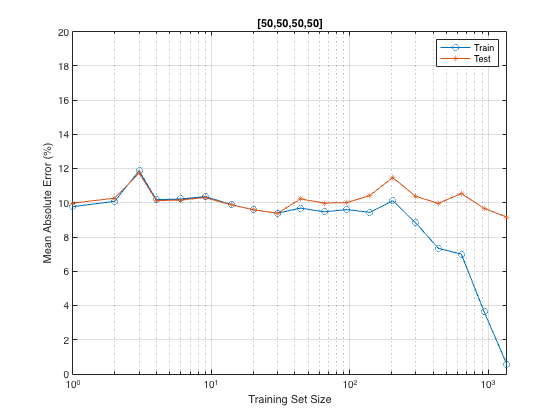

rnetModels4_50={};
dataSizes = floor(logspace(0, log10(height(trainInput)),20 ));
L = floor(logspace(-3, log10(2), 20));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels4_50{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [50,50,50,50], 'Lambda', 0.001);
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels4_50{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels4_50{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end
clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
title("[50,50,50,50]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

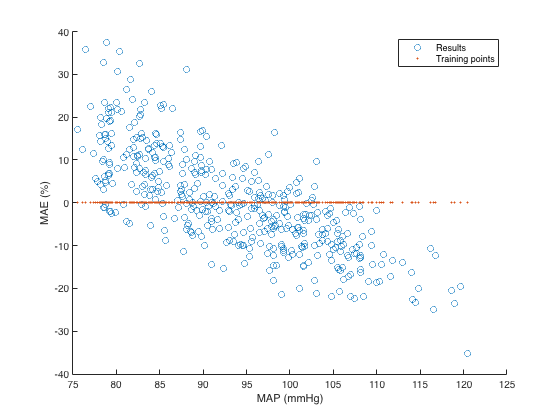




tErr = predict(rnetModels4_50{20}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
clf
scatter(actualTestMAP, (tErr-actualTestMAP)./actualTestMAP.*100)
hold on
scatter(actualTestMAP, 0.*actualTestMAP, '.')
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
legend("Results", "Training points")

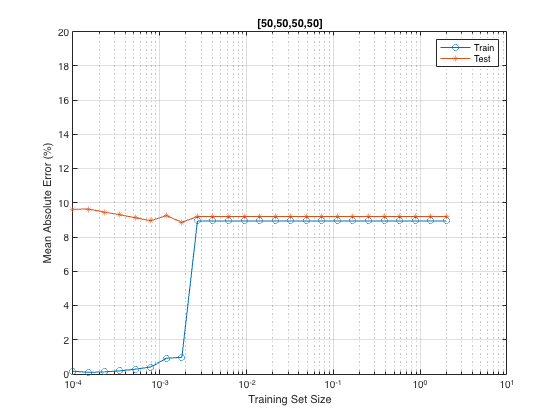

rnetModels4_50={};
L = logspace(-4, log10(2), 25);
trainingError=[];
testingError=[];

for idx=1:length(L)
    rnetModels4_50{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [50,50,50,50], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels4_50{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels4_50{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end
clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[50,50,50,50]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

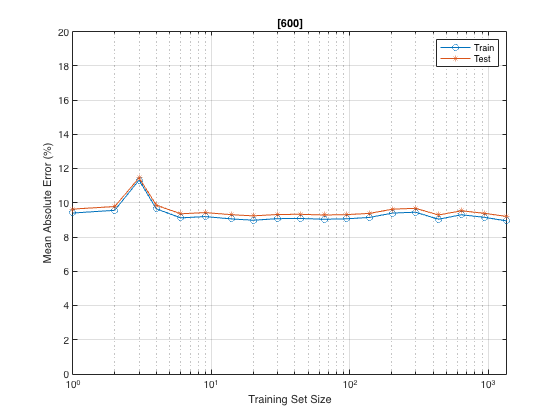

rnetModels1_600={};
dataSizes = floor(logspace(0, log10(height(trainInput)),5 ));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels1_600{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [600], 'Lambda', 1);

    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels1_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels1_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
title("[600]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

% pool = parpool
rnetModels1_600a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
    'LayerSizes', [600], 'Lambda', 1e-3);

actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels1_600a, testInput,'useParallel','yes')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP)

testingError = 0.0809


actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels1_600a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP)

trainingError = 0.0194


clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

rnetModels1_600={};
L = logspace(-4, log10(2), 5);
trainingError=[];
testingError=[];

parfor idx=1:length(L)
    fprintf("iter %i",idx)
    rnetModels1_600{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [600], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels1_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels1_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

iter 1iter 5iter 2iter 3iter 4

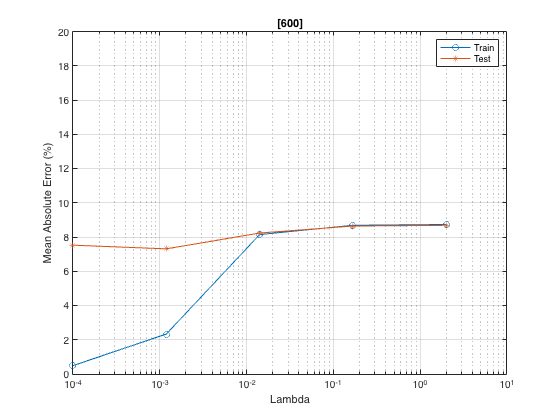

clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[600]")
ylim([0,20])
xlabel("Lambda")
ylabel("Mean Absolute Error (%)")
grid on

rnetModels3_600={};
L = logspace(-4, log10(2), 25);
trainingError=[];
testingError=[];

for idx=1:length(L)
    idx
    rnetModels3_600{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [600,600,600], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels3_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels3_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

idx = 1

idx = 2

idx = 3

clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[600,600,600]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

#### LSTM

[https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html](https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html)

see sequence to sequence regression

[https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-regression-using-deep-learning.html)

addSubPaths();
opts = readOptionsStruct();
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = [];
outputFeats = [];

interp_pts = 0:0.01:18;

for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        return; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    interp_ppg = interp1(time, ppg_wave, interp_pts);
    interp_abp = interp1(time, abp_wave, interp_pts);
    [f, PPG_fft] = singlesidedFFT(interp_pts, interp_ppg);
    stopIdx = find(f >= 20,1);
    [~, ABP_fft] = singlesidedFFT(interp_pts, interp_abp);
    
    inputFeats(idx, :) = [abs(PPG_fft(1:stopIdx)), angle(PPG_fft(1:stopIdx))];
    outputFeats(idx,:) = [abs(ABP_fft(1:stopIdx)), angle(ABP_fft(1:stopIdx))];

end

  1818

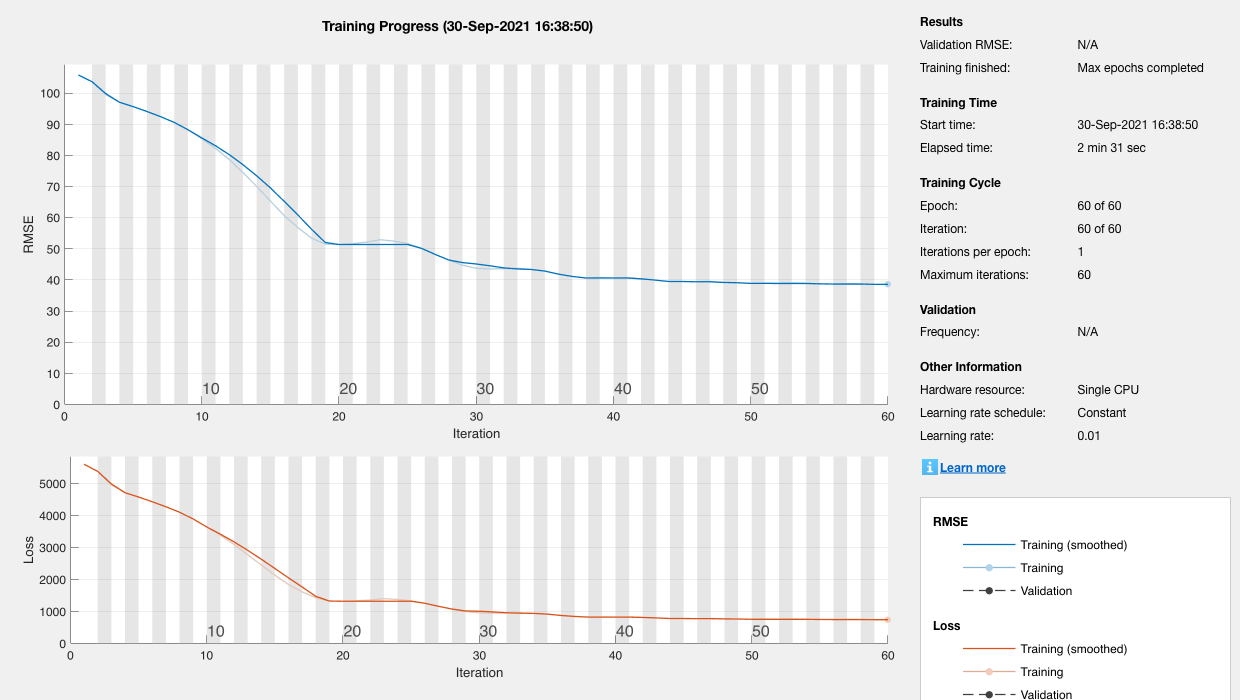

partition_variable = cvpartition(height(inputFeats), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInputF = inputFeats(trainingIndices,:);
trainOutputF = outputFeats(trainingIndices,:);

testIndices = test(partition_variable);
testInputF = inputFeats(testIndices,:);
testOutputF = outputFeats(testIndices,:); 


numFeatures = width(trainInputF);
numResponses = width(trainOutputF);
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.1)
    fullyConnectedLayer(numResponses)
    regressionLayer];

maxEpochs = 60;
miniBatchSize = 20;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',0.01, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'Verbose',0);

net = trainNetwork(trainInputF',trainOutputF',layers,options);



YPred = predict(net,testInputF(200,:)','MiniBatchSize',1)

YPred = 724×1 single column vector
   72.7032
    0.6954
    0.6353
    0.4627
    0.4844
    0.5656
    0.7550
    0.6841
    0.3323
    0.4800


actFFT = testOutputF(200,1:362).*exp(i.*testOutputF(200,363:end));
PredFFT = YPred(1:362).*exp(i.*YPred(363:end));
deltaf = 1/(0.01.*1801);
[pred_time, pred_abp] = singlesidedIFFT([0:deltaf:20+deltaf], PredFFT);
[act_time, act_abp] = singlesidedIFFT([0:deltaf:20+deltaf], actFFT);

clf
plot(pred_time, pred_abp)
hold on
plot(act_time, act_abp)

## DEEP LEARNING

If feature extraction -> ML -> output fails we can try reproduce some of the studies that used the entire PPG waveform with a deep learning model

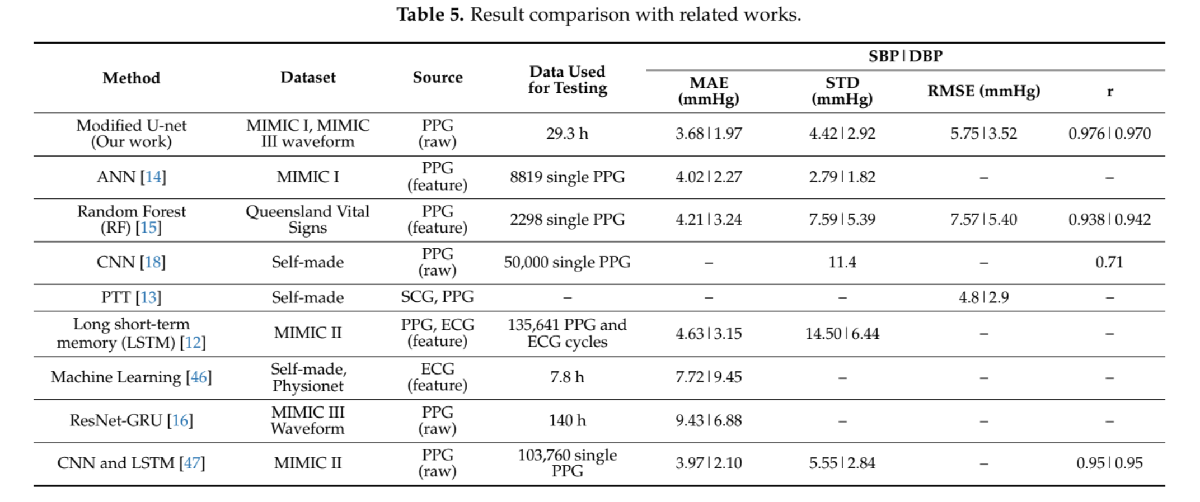

source: T. Athaya, S. Choi "An Estimation Method of Continuous Non-Invasive Arterial Blood Pressure Waveform Using Photoplethysmography: A U-Net Architecture-Based Approach" p. 13